clc;
clear;
close all;
waypoints = [
    0   0   0;
    2   0   1;
    4   2   2;
    2   4   2;
    0   2   1;
    0   0   0];
N = size(waypoints, 1);

waypointTime = [0;2;4;6;8;10];

disp('Waypoint matrix:');

Waypoint matrix:


disp(waypoints);

     0     0     0
     2     0     1
     4     2     2
     2     4     2
     0     2     1
     0     0     0




disp('Waypoint times (s):');

Waypoint times (s):


disp(waypointTime);

     0
     2
     4
     6
     8
    10




fprintf('Number of waypoints = %d\n', N);

Number of waypoints = 6


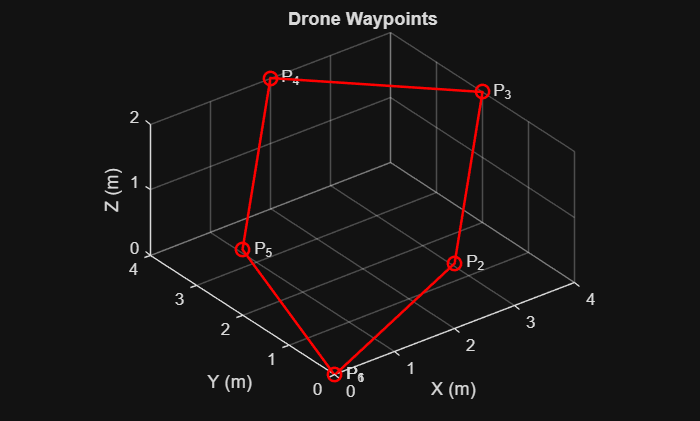


figure;

plot3(waypoints(:,1), ...
      waypoints(:,2), ...
      waypoints(:,3), ...
      'ro-', ...
      'LineWidth', 1.5, ...
      'MarkerSize', 8);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Drone Waypoints');

% Label each waypoint
for i = 1:N

    text(waypoints(i,1), ...
         waypoints(i,2), ...
         waypoints(i,3), ...
         sprintf('  P_%d', i), ...
         'FontSize', 10);

end

save('drone_toy_model.mat', ...
     'waypoints', ...
     'waypointTime');